% MATLAB Assignment: Finite Difference Time Domain (FDTD) Simulation

%% Task 1: Initialization 

% Clear all variables and close all figures
clear all;
close all;
clc;

% Physical constants
c = 3e8;                    
e0 = 8.854187817e-12;       
mu0 = 1.2566370614e-6;  
eta0 = sqrt(mu0 / e0); % impedance of free space

% Computational domain parameters
Nz = 2000;                  % Number of spatial grid points
dz = 10e-9;                 % Spatial grid spacing (10 nm)
zVec = (0:(Nz-1)) * dz;     % Spatial grid vector (from 0 to (Nz-1)*dz)

% Time discretization
dt = dz / (2 * c); % time step size 
total_timesteps = 8000; % total number of time steps
tVec = (0:(total_timesteps-1)) * dt; % time vector

% Check the Courant stability condition
S = c * dt / dz;
disp(['Courant number (S) = ', num2str(S)]); 

Courant number (S) = 0.5



% Initial pulse parameters
am = 1;                     % Amplitude 
la = 0.8e-6;                % Wavelength (800 nm)
freq = c / la;              
om = 2 * pi * freq;         % Angular frequency
el = 3e-6;                  % Total pulse width (3 um)
zc = 6e-6;                  % Initial pulse center position (6 um)
tau = el / c;               % Total pulse duration
tau_delay = tau;            % Time until center of pulse enters

% Initial conditions for source on boundary
Ey = zeros(1, Nz);          % Initial electric field (Ey component) along the spatial grid
Hy = zeros(1, Nz);          % Initial magnetic field (Hy component) along the spatial grid

% Time-varying source at position k = 1 (left boundary)
Source_Ey_t = (e0^(-1/2)) * am * exp(-((tVec - 2 * tau) ./ tau).^2) .* cos((tVec - tau_delay) * om);

% Fields recorded at different times
EE = zeros(total_timesteps, Nz); % Initialize E-field matrix (time x space)
num_samples = 1000;              % Number of samples for undersampled E-field
sampling_interval = floor(total_timesteps / num_samples);
EE_undersampled = zeros(num_samples, Nz); % Undersampled E-field matrix
tVec_undersampled = tVec(1:sampling_interval:end);

% Relative permittivity epsilon (er)
er = ones(1, Nz);            % Relative permittivity is 1 everywhere initially (vacuum)
epsilon = e0 * er;           % Absolute permittivity
mu = mu0 * ones(1, Nz);      % Absolute permeability

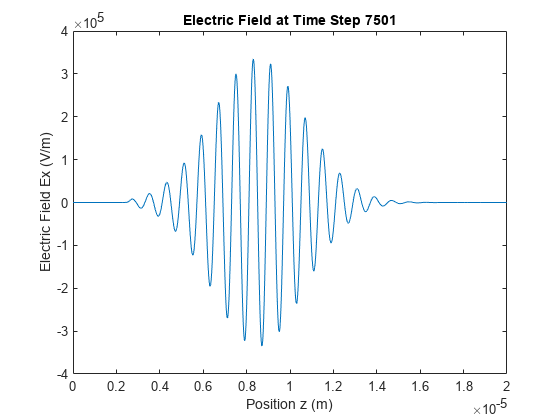

%% Task 2: Implement FDTD Method with For-Loops

% In this section,FDTD method using explicit for-loops over each index.

% Initialize Ex and Hy arrays
Ex = zeros(1, Nz);           % Electric field (Ex component) along the spatial grid
Hy = zeros(1, Nz);           % Magnetic field (Hy component) along the spatial grid

% For-loop version of the FDTD time integration
% Note: We will store the E-field at each time step for plotting purposes

for n = 1:total_timesteps
    % Update magnetic field Hy
    for k = 1:(Nz - 1)
        Hy(k) = Hy(k) - (dt / (mu(k) * dz)) * (Ex(k + 1) - Ex(k));
    end
    
    % Update electric field Ex
    for k = 2:Nz-1
        Ex(k) = Ex(k) - (dt / (epsilon(k) * dz)) * (Hy(k) - Hy(k - 1));
    end
    
    % Apply source at k = 1
    Ex(1) = Source_Ey_t(n);
    
    % Save the E-field at this time step
    EE(n, :) = Ex;
end

% Plot the E-field at various times (Time-varying plots)
figure;
for n = 1:500:total_timesteps
    plot(zVec, EE(n, :));
    xlabel('Position z (m)');
    ylabel('Electric Field Ex (V/m)');
    title(['Electric Field at Time Step ', num2str(n)]);
    drawnow;
    pause(0.1);
end


%% Task 3: Implement FDTD Method with Vectorization

% In this section FDTD method using vectorized operations to improve performance.

% Reset Ex and Hy arrays
Ex = zeros(1, Nz);           % Electric field (Ex component)
Hy = zeros(1, Nz);           % Magnetic field (Hy component)

% Reset EE matrix
EE_vec = zeros(total_timesteps, Nz);

% Vectorized version of the FDTD time integration

for n = 1:total_timesteps
    % Update magnetic field Hy
    Hy(1:Nz-1) = Hy(1:Nz-1) - (dt ./ (mu(1:Nz-1) * dz)) .* (Ex(2:Nz) - Ex(1:Nz-1));
    
    % Update electric field Ex
    Ex(2:Nz-1) = Ex(2:Nz-1) - (dt ./ (epsilon(2:Nz-1) * dz)) .* (Hy(2:Nz-1) - Hy(1:Nz-2));
    
    % Apply source at k = 1
    Ex(1) = Source_Ey_t(n);
    
    % Save the E-field at this time step
    EE_vec(n, :) = Ex;
end

% Plot the E-field at various times
figure;
for n = 1:500:total_timesteps
    plot(zVec, EE_vec(n, :));
    xlabel('Position z (m)');
    ylabel('Electric Field Ex (V/m)');
    title(['Electric Field at Time Step ', num2str(n)]);
    drawnow;
    pause(0.1);
end

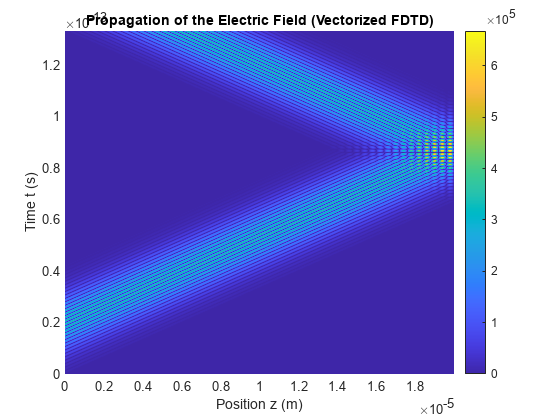


% Generate a 3D plot 

% Undersample the E-field for plotting purposes
EE_undersampled = EE_vec(1:sampling_interval:end, :);
tVec_undersampled = tVec(1:sampling_interval:end);

% Create a 3D plot of the absolute value of the E-field using pcolor
figure;
pcolor(zVec, tVec_undersampled, abs(EE_undersampled));
shading interp;
xlabel('Position z (m)');
ylabel('Time t (s)');
title('Propagation of the Electric Field (Vectorized FDTD)');
colorbar;


%% Task 4: Compare Execution Times Using MATLAB Profiler

% Measure execution time of the for-loop version
tic;
[EE_for, time_for] = fdtd_for_loop(Nz, total_timesteps, dz, dt, epsilon, mu, Source_Ey_t);
toc_time_for = toc;

% Measure execution time of the vectorized version
tic;
[EE_vec, time_vec] = fdtd_vectorized(Nz, total_timesteps, dz, dt, epsilon, mu, Source_Ey_t);
toc_time_vec = toc;

% Display the execution times
disp(['Execution time (For Loops): ', num2str(toc_time_for), ' seconds']);

Execution time (For Loops): 0.35149 seconds


disp(['Execution time (Vectorized): ', num2str(toc_time_vec), ' seconds']);

Execution time (Vectorized): 0.42054 seconds



% Note: In practice, the vectorized version should be significantly faster than the for-loop version.


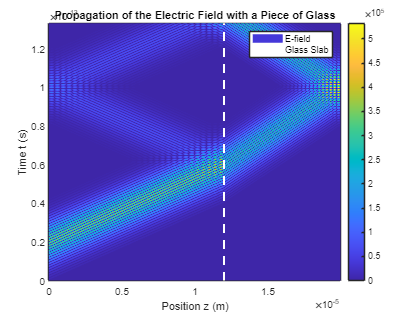

%% Task 5: Insert a Piece of Glass at z0 = 12 microns

% Modify the relative permittivity er to represent the piece of glass
er_glass = ones(1, Nz);
z0 = 12e-6;                 % Position of the glass (12 microns)
% Find the index in zVec corresponding to z0
[~, k_glass] = min(abs(zVec - z0));
er_glass(k_glass:end) = 1.5^2; 

% Recalculate epsilon with the new er
epsilon_glass = e0 * er_glass;

% Reset Ex and Hy arrays
Ex = zeros(1, Nz);           % Electric field (Ex component)
Hy = zeros(1, Nz);           % Magnetic field (Hy component)

% Reset EE matrix
EE_glass = zeros(total_timesteps, Nz);

% Run the vectorized FDTD simulation with the piece of glass
for n = 1:total_timesteps
    % Update magnetic field Hy
    Hy(1:Nz-1) = Hy(1:Nz-1) - (dt ./ (mu(1:Nz-1) * dz)) .* (Ex(2:Nz) - Ex(1:Nz-1));
    
    % Update electric field Ex
    Ex(2:Nz-1) = Ex(2:Nz-1) - (dt ./ (epsilon_glass(2:Nz-1) * dz)) .* (Hy(2:Nz-1) - Hy(1:Nz-2));
    
    % Apply source at k = 1
    Ex(1) = Source_Ey_t(n);
    
    % Save the E-field at this time step
    EE_glass(n, :) = Ex;
end

% Undersample the E-field for plotting purposes
EE_glass_undersampled = EE_glass(1:sampling_interval:end, :);

% Create a 3D plot
figure;
pcolor(zVec, tVec_undersampled, abs(EE_glass_undersampled));
shading interp;
xlabel('Position z (m)');
ylabel('Time t (s)');
title('Propagation of the Electric Field with a Piece of Glass');
colorbar;
hold on;
% Plot the position of the glass slab
plot([z0 z0], [tVec_undersampled(1) tVec_undersampled(end)], 'w--', 'LineWidth', 2);
legend('E-field', 'Glass Slab');
hold off;


% Observations:
% The plot should show the incident pulse propagating towards the glass slab at z = 12 microns.
% Upon reaching the glass slab, part of the pulse is reflected, and part is transmitted into the glass.
% The transmitted pulse propagates more slowly inside the glass due to the higher refractive index.

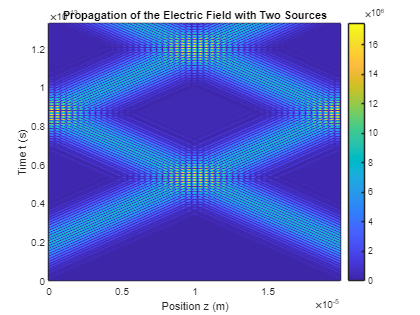


%% Task 6: Initialize Two Time-Varying Sources at Both Ends

% Reset the relative permittivity er to 1 everywhere (no glass)
er = ones(1, Nz);
epsilon = e0 * er;

% Reset Ex and Hy arrays
Ex = zeros(1, Nz);           % Electric field (Ex component)
Hy = zeros(1, Nz);           % Magnetic field (Hy component)

% Reset EE matrix
EE_two_sources = zeros(total_timesteps, Nz);

% Create a second source at the right boundary (k = Nz)
Source_Ey_t_right = Source_Ey_t; % Use the same source

% Run the vectorized FDTD simulation with two sources
for n = 1:total_timesteps
    % Update magnetic field Hy
    Hy(1:Nz-1) = Hy(1:Nz-1) - (dt ./ (mu(1:Nz-1) * dz)) .* (Ex(2:Nz) - Ex(1:Nz-1));
    
    % Update electric field Ex
    Ex(2:Nz-1) = Ex(2:Nz-1) - (dt ./ (epsilon(2:Nz-1) * dz)) .* (Hy(2:Nz-1) - Hy(1:Nz-2));
    
    % Apply source at k = 1 (left boundary)
    Ex(1) = Ex(1) + Source_Ey_t(n);
    
    % Apply source at k = Nz (right boundary)
    Ex(Nz) = Ex(Nz) + Source_Ey_t_right(n);
    
    % Save the E-field at this time step
    EE_two_sources(n, :) = Ex;
end

% Undersample the E-field for plotting purposes
EE_two_sources_undersampled = EE_two_sources(1:sampling_interval:end, :);

% Create a 3D plot 
figure;
pcolor(zVec, tVec_undersampled, abs(EE_two_sources_undersampled));
shading interp;
xlabel('Position z (m)');
ylabel('Time t (s)');
title('Propagation of the Electric Field with Two Sources');
colorbar;


% Observations:
% The plot should show two pulses propagating towards each other from both ends of the domain.
% When they overlap, you should observe an interference pattern characteristic of the superposition of two waves.
% The interference can be constructive or destructive, leading to a pattern that looks like standing waves.


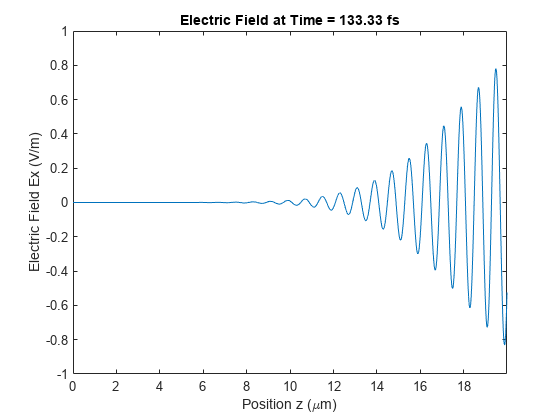

% Initial pulse parameters
am = 1; % amplitude (arbitrary units)
la = 0.8e-6; % wavelength (800 nm)
freq = c / la; % frequency
tau = 2e-14; % pulse width
t0 = 3 * tau; % pulse delay

% Initial conditions for source
Ex = zeros(1, Nz); % electric field (Ex component) along the spatial grid
Hy = zeros(1, Nz); % magnetic field (Hy component) along the spatial grid

% Fields recorded at different times
num_samples = 200;
sampling_interval = floor(total_timesteps / num_samples);
EE = zeros(num_samples, Nz); % undersampled E-field matrix
tVec_sampled = tVec(1:sampling_interval:end);

% Relative permittivity epsilon (er)
er = ones(1, Nz); % relative permittivity is 1 everywhere initially (vacuum)
epsilon = e0 * er; % absolute permittivity
mu = mu0 * ones(1, Nz); % absolute permeability

%% Section 2: Implement FDTD Method with Vectorization and Mur's Boundary Conditions

% Implement Mur's absorbing boundary conditions
% Initialize previous Ex values at boundaries for Mur's boundary conditions
Ex_low_m1 = 0; % Ex at left boundary at time n-1
Ex_high_m1 = 0; % Ex at right boundary at time n-1

% Source position
k_source = 50; % Position of the source (avoid boundaries)

% Run the FDTD simulation
n_samples = 0; % Counter for samples
figure;
for n = 1:total_timesteps
    % Update magnetic field Hy
    Hy(1:Nz-1) = Hy(1:Nz-1) + (dt / (mu0 * dz)) * (Ex(2:Nz) - Ex(1:Nz-1));
    
    % Update electric field Ex
    Ex(2:Nz-1) = Ex(2:Nz-1) + (dt / (e0 * dz)) * (Hy(2:Nz-1) - Hy(1:Nz-2));
    
    % Apply electric field source at k_source
    t = n * dt;
    Ex(k_source) = Ex(k_source) + exp(-((t - t0) / tau)^2) * sin(2 * pi * freq * t);
    
    % Implement Mur's absorbing boundary conditions
    % Left boundary (k = 1)
    Ex(1) = Ex_low_m1 + ((S - 1) / (S + 1)) * (Ex(2) - Ex(1));
    Ex_low_m1 = Ex(2);
    
    % Right boundary (k = Nz)
    Ex(Nz) = Ex_high_m1 + ((S - 1) / (S + 1)) * (Ex(Nz-1) - Ex(Nz));
    Ex_high_m1 = Ex(Nz-1);
    
    % Record the E-field at sampled time steps
    if mod(n, sampling_interval) == 0
        n_samples = n_samples + 1;
        EE(n_samples, :) = Ex;
        
        % Plotting the E-field at current time step
        plot(zVec * 1e6, Ex);
        xlabel('Position z (\mum)');
        ylabel('Electric Field Ex (V/m)');
        title(['Electric Field at Time = ', num2str(t * 1e15, '%.2f'), ' fs']);
        axis([0 max(zVec) * 1e6 -1 1]);
        drawnow;
    end
end

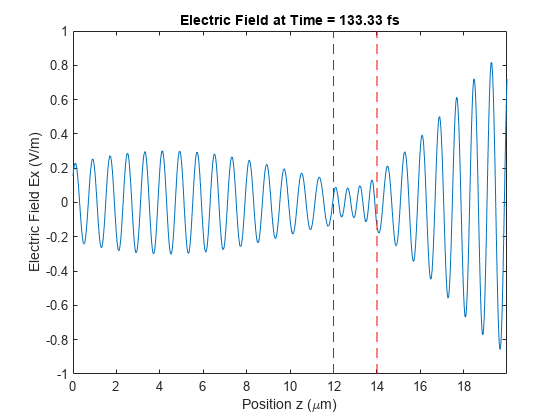

%% Section 4: Insert a Piece of Glass at z0 = 12 microns

% Modify the relative permittivity er to represent the piece of glass
er_glass = ones(1, Nz);
z0 = 12e-6; % position of the glass (12 microns)
thickness = 2e-6; % thickness of the glass (2 microns)
z1 = z0 + thickness;
k_glass_start = round(z0 / dz);
k_glass_end = round(z1 / dz);

er_glass(k_glass_start:k_glass_end) = 1.5^2; % n^2 = (1.5)^2 = 2.25

% Recalculate epsilon with the new er
epsilon_glass = e0 * er_glass;

% Reset Ex and Hy arrays
Ex = zeros(1, Nz);
Hy = zeros(1, Nz);

% Implement Mur's absorbing boundary conditions
Ex_low_m1 = 0;
Ex_high_m1 = 0;

% Run the FDTD simulation with the piece of glass
n_samples = 0;
EE_glass = zeros(num_samples, Nz);
figure;
for n = 1:total_timesteps
    % Update magnetic field Hy
    Hy(1:Nz-1) = Hy(1:Nz-1) + (dt ./ (mu0 * dz)) .* (Ex(2:Nz) - Ex(1:Nz-1));
    
    % Update electric field Ex
    Ex(2:Nz-1) = Ex(2:Nz-1) + (dt ./ (epsilon_glass(2:Nz-1) * dz)) .* (Hy(2:Nz-1) - Hy(1:Nz-2));
    
    % Apply source at k_source
    t = n * dt;
    Ex(k_source) = Ex(k_source) + exp(-((t - t0) / tau)^2) * sin(2 * pi * freq * t);
    
    % Implement Mur's absorbing boundary conditions
    % Left boundary
    Ex(1) = Ex_low_m1 + ((S - 1) / (S + 1)) * (Ex(2) - Ex(1));
    Ex_low_m1 = Ex(2);
    
    % Right boundary
    Ex(Nz) = Ex_high_m1 + ((S - 1) / (S + 1)) * (Ex(Nz-1) - Ex(Nz));
    Ex_high_m1 = Ex(Nz-1);
    
    % Record the E-field at sampled time steps
    if mod(n, sampling_interval) == 0
        n_samples = n_samples + 1;
        EE_glass(n_samples, :) = Ex;
        
        % Plotting the E-field at current time step
        plot(zVec * 1e6, Ex);
        xlabel('Position z (\mum)');
        ylabel('Electric Field Ex (V/m)');
        title(['Electric Field at Time = ', num2str(t * 1e15, '%.2f'), ' fs']);
        axis([0 max(zVec) * 1e6 -1 1]);
        hold on;
        % Indicate the glass region
        plot([z0 z0] * 1e6, [-1 1], 'r--');
        plot([z1 z1] * 1e6, [-1 1], 'r--');
        hold off;
        drawnow;
    end
end

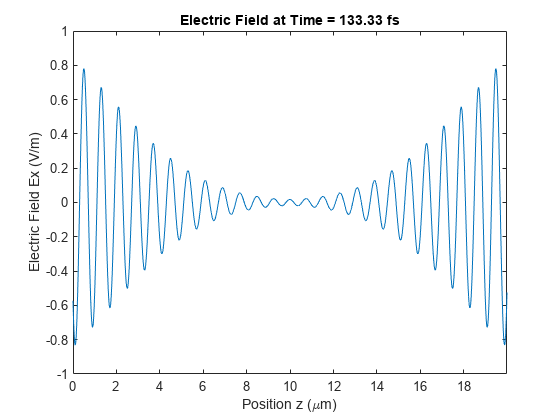

%% Section 6: Initialize Two Time-Varying Sources at Both Ends

% Reset er and epsilon
er = ones(1, Nz);
epsilon = e0 * er;

% Reset Ex and Hy arrays
Ex = zeros(1, Nz);
Hy = zeros(1, Nz);

% Implement Mur's absorbing boundary conditions
Ex_low_m1 = 0;
Ex_high_m1 = 0;

% Second source position
k_source_right = Nz - 50;

% Run the FDTD simulation with two sources
n_samples = 0;
EE_two = zeros(num_samples, Nz);
figure;
for n = 1:total_timesteps
    % Update magnetic field Hy
    Hy(1:Nz-1) = Hy(1:Nz-1) + (dt ./ (mu0 * dz)) .* (Ex(2:Nz) - Ex(1:Nz-1));
    
    % Update electric field Ex
    Ex(2:Nz-1) = Ex(2:Nz-1) + (dt ./ (e0 * dz)) .* (Hy(2:Nz-1) - Hy(1:Nz-2));
    
    % Apply source at k_source (left)
    t = n * dt;
    Ex(k_source) = Ex(k_source) + exp(-((t - t0) / tau)^2) * sin(2 * pi * freq * t);
    
    % Apply source at k_source_right (right)
    Ex(k_source_right) = Ex(k_source_right) + exp(-((t - t0) / tau)^2) * sin(2 * pi * freq * t);
    
    % Implement Mur's absorbing boundary conditions
    % Left boundary
    Ex(1) = Ex_low_m1 + ((S - 1) / (S + 1)) * (Ex(2) - Ex(1));
    Ex_low_m1 = Ex(2);
    
    % Right boundary
    Ex(Nz) = Ex_high_m1 + ((S - 1) / (S + 1)) * (Ex(Nz-1) - Ex(Nz));
    Ex_high_m1 = Ex(Nz-1);
    
    % Record the E-field at sampled time steps
    if mod(n, sampling_interval) == 0
        n_samples = n_samples + 1;
        EE_two(n_samples, :) = Ex;
        
        % Plotting the E-field at current time step
        plot(zVec * 1e6, Ex);
        xlabel('Position z (\mum)');
        ylabel('Electric Field Ex (V/m)');
        title(['Electric Field at Time = ', num2str(t * 1e15, '%.2f'), ' fs']);
        axis([0 max(zVec) * 1e6 -1 1]);
        drawnow;
    end
end

function [EE, exec_time] = fdtd_for_loop(Nz, total_timesteps, dz, dt, epsilon, mu, Source_Ey_t)
    Ex = zeros(1, Nz);
    Hy = zeros(1, Nz);
    EE = zeros(total_timesteps, Nz);
    tic;
    for n = 1:total_timesteps
        % Update magnetic field Hy
        for k = 1:(Nz - 1)
            Hy(k) = Hy(k) - (dt / (mu(k) * dz)) * (Ex(k + 1) - Ex(k));
        end
        
        % Update electric field Ex
        for k = 2:Nz-1
            Ex(k) = Ex(k) - (dt / (epsilon(k) * dz)) * (Hy(k) - Hy(k - 1));
        end
        
        % Apply source at k = 1
        Ex(1) = Source_Ey_t(n);
        
        % Save the E-field at this time step
        EE(n, :) = Ex;
    end
    exec_time = toc;
end

% Function for FDTD with vectorization
function [EE, exec_time] = fdtd_vectorized(Nz, total_timesteps, dz, dt, epsilon, mu, Source_Ey_t)
    Ex = zeros(1, Nz);
    Hy = zeros(1, Nz);
    EE = zeros(total_timesteps, Nz);
    tic;
    for n = 1:total_timesteps
        % Update magnetic field Hy
        Hy(1:Nz-1) = Hy(1:Nz-1) - (dt ./ (mu(1:Nz-1) * dz)) .* (Ex(2:Nz) - Ex(1:Nz-1));
        
        % Update electric field Ex
        Ex(2:Nz-1) = Ex(2:Nz-1) - (dt ./ (epsilon(2:Nz-1) * dz)) .* (Hy(2:Nz-1) - Hy(1:Nz-2));
        
        % Apply source at k = 1
        Ex(1) = Source_Ey_t(n);
        
        % Save the E-field at this time step
        EE(n, :) = Ex;
    end
    exec_time = toc;
end


